## Optimizer

% OPTI_DATA1_5 = cell2mat(struct2cell(load('OPTIDATA1_5.mat')));
% OPTI_DATA6_10 = cell2mat(struct2cell(load('OPTIDATA6_10.mat')));
% OPTI_DATA11_20 = cell2mat(struct2cell(load('OPTIDATA_REST.mat')));
% 
% OPTI_DATA = [OPTI_DATA1_5 ; OPTI_DATA6_10 ; OPTI_DATA11_20];
% save('OPTIDATA_FULL','OPTI_DATA');

load('OPTIDATA_FULL.mat','OPTI_DATA');
% Parameters
C_c = 5*[30000 2000 1800 5000 3000]; % Euro per component per area
C_jit = 10000; % Euro per hour deviation
C_r = 3000; % Euro per resource
D_r = 3.5; % Hour drive
C_at = 20000; % Euro per transfer
S_d = 1; % Desired sigma level
% Decision variables
n_R = []; % Number of resources
n_AT = []; % Number of annual transfers
% Constraints
B_n_R = 1:20;
B_n_AT = 3:24;
% Objective function
%[n_R n_AT] = min(); % Minimalize costs

% 3D matrix build
S_d = 1; % Desired sigma level
[r c] = size(OPTI_DATA); % Measures size
A = zeros(20,5); % Builds an empty 3x3 matrix
for i = 2:20
    A(:,:,i) = zeros(20,5);
end
for i = 1:20 % 20
    for k = [3 4 6 12 24]
        for l = 1:20
            for line = 1:r
                if OPTI_DATA(line,[1:3]) == [i,l,k]
                    C_tinv = sum(C_c.*ceil(S_d*(OPTI_DATA(line,[5:9]).^1))); % Inventory costs
                    C_tat = C_at*OPTI_DATA(line,3); % Transfer costs
                    C_tr = C_r*OPTI_DATA(line,3)*OPTI_DATA(line,2)^(1.2); % Resource costs
                    C_tjit = C_jit*OPTI_DATA(line,3)*2*D_r*(1+OPTI_DATA(line,4))^2;%C_jit*OPTI_DATA(line,3)*(1+OPTI_DATA(line,4))^2; % Costs of delays
                    % ADD NUMBER OF SCHEDULED COMPONENTS
                    if k == 3
                        A(l,1,i) = C_tinv + C_tat + C_tr + C_tjit; % Sum of all costs
                    elseif k == 4
                        A(l,2,i) = C_tinv + C_tat + C_tr + C_tjit; % Sum of all costs
                    elseif k == 6
                        A(l,3,i) = C_tinv + C_tat + C_tr + C_tjit; % Sum of all costs
                    elseif k == 12
                        A(l,4,i) = C_tinv + C_tat + C_tr + C_tjit; % Sum of all costs
                    elseif k == 24
                        A(l,5,i) = C_tinv + C_tat + C_tr + C_tjit; % Sum of all costs
                    end
                end
            end
        end
    end
end

for i = 1:20
    Aarr = A(:,:,i);
    Amin = min(min(Aarr));
    [x(i),y(i)]=find(Aarr==Amin);
end

% 3D matrix build
S_d = 2; % Desired sigma level
[r c] = size(OPTI_DATA); % Measures size
A = zeros(20,5); % Builds an empty 3x3 matrix
for i = 2:20
    A(:,:,i) = zeros(20,5);
end
for i = 1:20 % 20
    for k = [3 4 6 12 24]
        for l = 1:20
            for line = 1:r
                if OPTI_DATA(line,[1:3]) == [i,l,k]
                    C_tinv = sum(C_c.*ceil(S_d*(OPTI_DATA(line,[5:9]).^1))); % Inventory costs
                    C_tat = C_at*OPTI_DATA(line,3); % Transfer costs
                    C_tr = C_r*OPTI_DATA(line,3)*OPTI_DATA(line,2)^(1.2); % Resource costs
                    C_tjit = C_jit*OPTI_DATA(line,3)*2*D_r*(1+OPTI_DATA(line,4))^2;%C_jit*OPTI_DATA(line,3)*(1+OPTI_DATA(line,4))^2; % Costs of delays
                    % ADD NUMBER OF SCHEDULED COMPONENTS
                    if k == 3
                        A(l,1,i) = C_tinv + C_tat + C_tr + C_tjit; % Sum of all costs
                    elseif k == 4
                        A(l,2,i) = C_tinv + C_tat + C_tr + C_tjit; % Sum of all costs
                    elseif k == 6
                        A(l,3,i) = C_tinv + C_tat + C_tr + C_tjit; % Sum of all costs
                    elseif k == 12
                        A(l,4,i) = C_tinv + C_tat + C_tr + C_tjit; % Sum of all costs
                    elseif k == 24
                        A(l,5,i) = C_tinv + C_tat + C_tr + C_tjit; % Sum of all costs
                    end
                end
            end
        end
    end
end

for i = 1:20
    Aarr = A(:,:,i);
    Amin = min(min(Aarr));
    [x2(i),y2(i)]=find(Aarr==Amin);
end

% 3D matrix build
S_d = 3; % Desired sigma level
[r c] = size(OPTI_DATA); % Measures size
A = zeros(20,5); % Builds an empty 3x3 matrix
for i = 2:20
    A(:,:,i) = zeros(20,5);
end
for i = 1:20 % 20
    for k = [3 4 6 12 24]
        for l = 1:20
            for line = 1:r
                if OPTI_DATA(line,[1:3]) == [i,l,k]
                    C_tinv = sum(C_c.*ceil(S_d*(OPTI_DATA(line,[5:9]).^1))); % Inventory costs
                    C_tat = C_at*OPTI_DATA(line,3); % Transfer costs
                    C_tr = C_r*OPTI_DATA(line,3)*OPTI_DATA(line,2)^(1.2); % Resource costs
                    C_tjit = C_jit*OPTI_DATA(line,3)*2*D_r*(1+OPTI_DATA(line,4))^2;%C_jit*OPTI_DATA(line,3)*(1+OPTI_DATA(line,4))^2; % Costs of delays
                    % ADD NUMBER OF SCHEDULED COMPONENTS
                    if k == 3
                        A(l,1,i) = C_tinv + C_tat + C_tr + C_tjit; % Sum of all costs
                    elseif k == 4
                        A(l,2,i) = C_tinv + C_tat + C_tr + C_tjit; % Sum of all costs
                    elseif k == 6
                        A(l,3,i) = C_tinv + C_tat + C_tr + C_tjit; % Sum of all costs
                    elseif k == 12
                        A(l,4,i) = C_tinv + C_tat + C_tr + C_tjit; % Sum of all costs
                    elseif k == 24
                        A(l,5,i) = C_tinv + C_tat + C_tr + C_tjit; % Sum of all costs
                    end
                end
            end
        end
    end
end

for i = 1:20
    Aarr = A(:,:,i);
    Amin = min(min(Aarr));
    [x3(i),y3(i)]=find(Aarr==Amin);
end

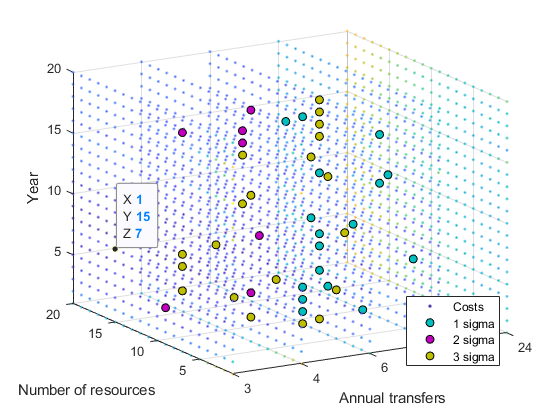


[Y,X,Z] = ndgrid(1:size(A,1), 1:size(A,2), 1:size(A,3));
pointsize = 30;
scatter3(X(:), Y(:), Z(:), pointsize, A(:), '.');
xlabel('Annual transfers')
xlim([1,5])
xticklabels({'3','4','6','12','24'})
ylabel('Number of resources')
ylim([1,20])
zlabel('Year')
zlim([1,20])
hold on
scatter3(y,x,1:20,...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 .75 .75])
scatter3(y2,x2,1:20,...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.75 0 .75])
scatter3(y3,x3,1:20,...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[.75 .75 0])
legend({'Costs','1 sigma','2 sigma','3 sigma'},'Location','best')
    hold off
view([-45 30])

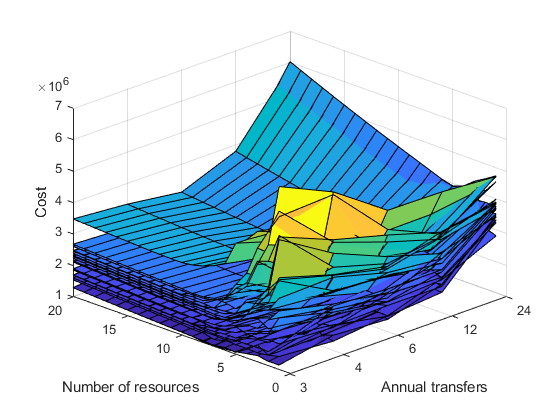

surf(A(:,:,1))
xlabel('Annual transfers')
xticklabels({'3','4','6','12','24'})
ylabel('Number of resources')
zlabel('Cost')
hold on
for i = 2:20
surf(A(:,:,i))
end
view([-45 30])

## Inventory

x = double(x);
y = double(y);
for q = 1:length(y)
    if y(q) == 1
        y(q) = 3;
    elseif y(q) == 2
        y(q) = 4;
    elseif y(q) == 3
        y(q) = 6;
    elseif y(q) == 4
        y(q) = 12;
    elseif y(q) == 5
        y(q) = 24
    end
end
x2 = double(x2);
y2 = double(y2);
for q = 1:length(y2)
    if y2(q) == 1
        y2(q) = 3;
    elseif y2(q) == 2
        y2(q) = 4;
    elseif y2(q) == 3
        y2(q) = 6;
    elseif y2(q) == 4
        y2(q) = 12;
    elseif y2(q) == 5
        y2(q) = 24
    end
end
x3 = double(x3);
y3 = double(y3);
for q = 1:length(y3)
    if y3(q) == 1
        y3(q) = 3;
    elseif y3(q) == 2
        y3(q) = 4;
    elseif y3(q) == 3
        y3(q) = 6;
    elseif y3(q) == 4
        y3(q) = 12;
    elseif y3(q) == 5
        y3(q) = 24
    end
end


[r c] = size(OPTI_DATA); % Measures size
for i = 1:20
    for line = 1:r
        if OPTI_DATA(line,[1:3]) == [i,x(i),y(i)]
            Inv(i,:) = OPTI_DATA(line,[5:9]);
        end
    end
end
[r c] = size(OPTI_DATA); % Measures size
for i = 1:20
    for line = 1:r
        if OPTI_DATA(line,[1:3]) == [i,x2(i),y2(i)]
            Inv2(i,:) = OPTI_DATA(line,[5:9]);
        end
    end
end
[r c] = size(OPTI_DATA); % Measures size
for i = 1:20
    for line = 1:r
        if OPTI_DATA(line,[1:3]) == [i,x3(i),y3(i)]
            Inv3(i,:) = OPTI_DATA(line,[5:9]);
        end
    end
end

Inv_s = {ceil(1.*Inv)};
Inv_s2 = {ceil(2.*Inv2)};
Inv_s3 = {ceil(3.*Inv3)};


